% Suppress useless warnings: 
warning('off', 'Ident:dataprocess:idinput7'); % prbs sequence length warning

% Bode plot options for later
bodeopts = bodeoptions('cstprefs');
bodeopts.Grid = 'on';

bode_no_phase = bodeopts;
bode_no_phase.PhaseVisible = 'off';

# VRFT Control Algorithm for a Quad Copter Platform

Normally to perfrom VRFT on a platform we would have a set of input-output data and an Idea of a reference model to use. I have neither. I should receive IO data soon but I still won't have any idea about the reference models to use. For a sensitive application such as this the choice of the reference models is essential, a mistaken choice will make the platform unstable and the control performance terrible. 

Instead we will work backwards. First we write the model from the information contained in the thesis, then calculate the complimentary sensitivity function based on the known controllers. This will become our reference model. 

We will use the model we wrote to generate output data from a PRBS input and use that to perform the VRFT on the plant. The controllers we obtain this way should be quite close to the original controllers. At a later time we might try to make the reference models faster and train a new controller with VRFT. 

Our first step now is to build the physical model.

## Building the Physical Model of the Pitch

Since we don't have access to real measurements yet we need to build the physical model to generate ou input - ouput data sets. The thesis provides us with enough information to do this.

The physical model of the system is: 


$$I_n \dot{\omega}_b + \omega_b \times \left( I_n \omega_b \right) = M_{Damp} + M_{props} \\
\qquad \qquad \qquad \quad \dot{\Theta} = q$$


Before going any further we need to calculate $I_{yy}$, $\frac{\partial M}{\partial q}$ and $\frac{\partial M}{\partial u}$. Whilst $I_{yy}$ and $\frac{\partial M}{\partial q}$are provided as estimated values, $\frac{\partial M}{\partial u}$ isn't. The grey box estimation procedure used to estimate the first two values only has two equations and can only estimate two variables. This leaves two options:

-  use the guessed value of $15 \cdot 10^{-3}\ Nms$

- Estimate it using equation 6.22 (p76) however this requires data that I have not been able to locate in the paper. The script file `dM-du-estimation.mlx` attempts to do this.  

Here we will use the guessed value. 

% Using estimated data from Table 6.2 (p79) for Iyy and dM_q
Iyy = 34.7e-3;   % kg m^2
dM_q = -46.3e-3; % N m s

% Using guess from equation 6.26 (p76) for dM_u
dM_u = 15e-3;    % Nms

And the corresponding state space form considering the state vector $x = \left[\ q \ \Theta\ \right]^T $ is:

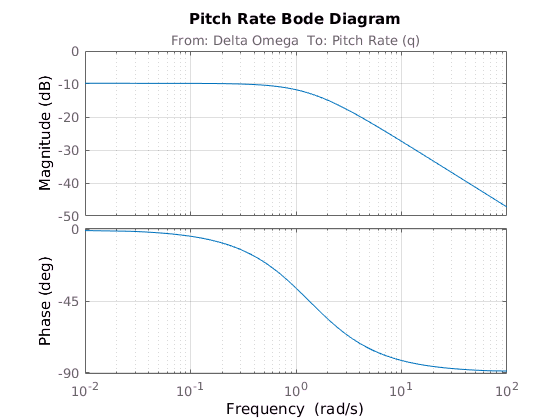

A = [
     1 / Iyy * dM_q,  0;
     1                0;
];

B = [1 / Iyy * dM_u; 0];
C = [1 0];
D = 0;

PitchRateModel = ss(A, B, C, D, ...
    'InputName', 'Delta Omega', 'OutputName', 'Pitch Rate (q)');

figure();
    bode(PitchRateModel);
    title('Pitch Rate Bode Diagram');
    grid on;

A brief comparison with figure 6.5 seems to show that this is a correct implementation of the model.

## The Original Controllers

We do not have standalone reference models at the moment. To begin with we can generate reference models from the known data. We will simply calculate the complementary sensitivity of the inner and outer loops and use thoses as reference models. 

With this approach the optimal controllers should be quite close to the $H_\infty$ controllers from the paper. At a later stage we might try to make faster controllers. 

As shown above the pitch control loop uses an inner PID controller and an outer PD controller. $K_P
$, $K_I$ and $K_D$ are tuned by the $H_{\infty}$ control law. $T_f$ was fixed manually beforehand. The outer controller is based on attitude feedback ($\Theta \rightarrow \Theta_0$) whilst the inner controller is based on angular rate feedback ($q \rightarrow q_0$). The PID parameters are given in table 7.1 (p87).

Tf = .01; % cf. p87 (Bottom right)

R1 = pid(.05, 1.61, .00512, Tf); % Inner
R2 = pid(.3 , 0   , .3    , Tf); % Outer

The final piece needed to realise the control loop is the mixer matrix. This matrix maps the required thrusts and moments around each axis to the rotational speed of the rotors. 

## The Mixer Matrix

The standard control scheme for a quad-copter uses a nested controller with a PID controller in the inner loop and a PD controller in the outer loop. 

The mixer matrix relates $\Omega_1^2 $, $\Omega_2^2$, $\Omega_3^2$ and $\Omega_4^2$ to the thrust and moments generated by the propellers. The calculations for this section are longer and will not be reported here. You can however find them on my [thesis log](http://thesis.comkieffer.com/modelling-is-like-plumbing.html).

Mixer = dM_u^-1;

## Connecting everything together

We now have all pieces of the puzzle. We just need to wire them together.

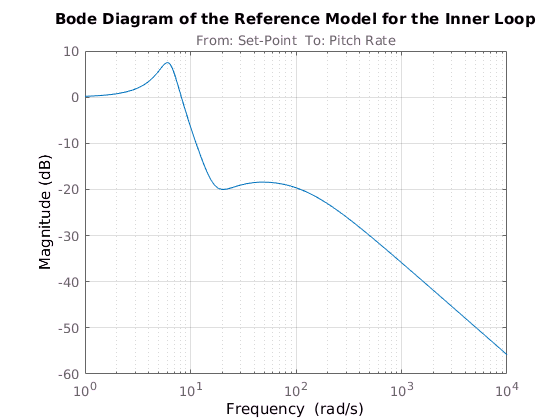

InnerLoop = loopsens(PitchRateModel * Mixer, R1);

InnerReferenceModel = tf(InnerLoop.Ti);
InnerReferenceModel.InputName = 'Set-Point'; 
InnerReferenceModel.OutputName = 'Pitch Rate';

figure(); 
    bode(InnerReferenceModel, bodeopts); 
    title('Bode Diagram of the Reference Model for the Inner Loop'); 

There is no plot I can use in the thesis to check that this reference model is correct. I have no idea what how wrong it is. 

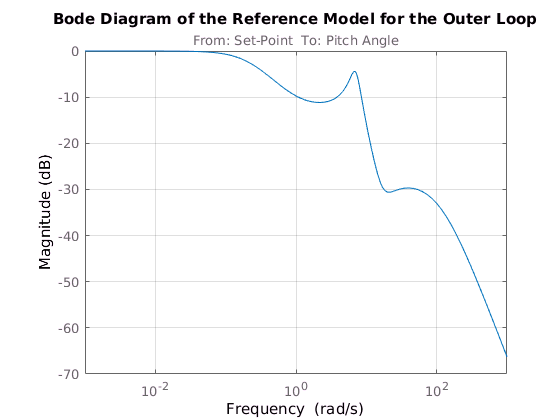

integrator = tf(1, [1 0]);
OuterLoop = loopsens(integrator * InnerReferenceModel, R2);

OuterReferenceModel = tf(OuterLoop.Ti);
OuterReferenceModel.InputName = 'Set-Point';
OuterReferenceModel.OutputName = 'Pitch Angle';

figure();
    bode(OuterReferenceModel, bodeopts); 
    title('Bode Diagram of the Reference Model for the Outer Loop');
    xlim([10^-3 10^3]); 

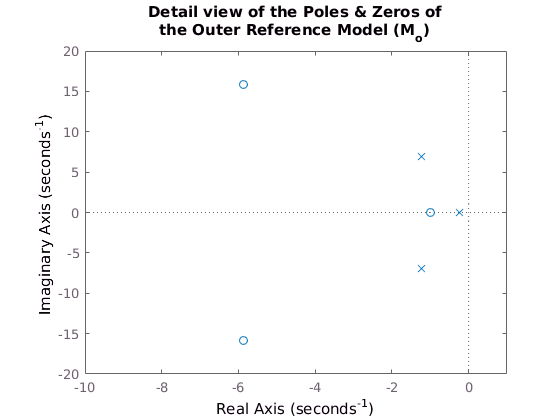

    
figure()
    pzmap(OuterReferenceModel);
    title({'Detail view of the Poles & Zeros of', 'the Outer Reference Model (M_o)'})
    xlim([-10, 1])

The only figure I can find in the thesis to validate this is figure 7.5. It looks nothing like this. This is a problem. 

## The VRFT Controller Classes

As previously stated the control structure for this problem comprises an inner PID controller and an outer PD controller. $C_i$is the inner controller and $C_o$is the outer controller. 


$$C_i(z) = K_{Pi} + K_{Ii} \frac{1}{s} + K_{Di} \frac{s}{1 + sT_f} $$



$$C_o(z) = k_{Po} + K_{Do} \frac{s}{1 + sT_f}$$


Tf = .01; % (cf: p87)

InnerControllerClass = [ 1, tf(1, [1 0]), tf([1 0], [Tf 1]) ].';
OuterControllerClass = [ 1,               tf([1 0], [Tf 1]) ].';

## Making the Input-Output Data

A PRBS sequence was used in the identification phase to estimate parameter values and it was suggested that I use a similar sequence as my IO data for the VRFT. Unfortunately I don't know the bandwidth to use or the precise lower and upper values. 

Until I have these the data might not be accurate.  The values chosen here are "best-guess" attempts at replicating the graphs in figure 6.6 (p80).

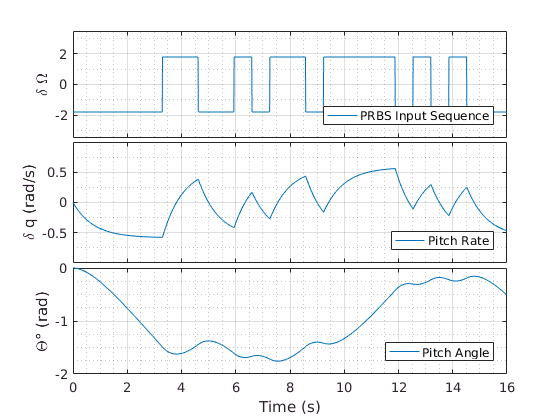

N = 1600;          % Eyeballed to make the data sequence have the right size. 
bw = .015;         % rad/s - Chosen more or less at random (bandwidth)
signal_peak = 1.8; % rad/s - Eyeballed from figure 6.6a (p(80)

time_vec = (0:(N-1)) * .01; % Sample time ? 

in = idinput(N, 'prbs', [0 bw], [-signal_peak, signal_peak]);

yi = lsim(PitchRateModel, in, time_vec);
yo = lsim(integrator, yi, time_vec);

fh = figure();
    subplot 311; 
        plot(time_vec, in);  
        legend('PRBS Input Sequence', 'location', 'SouthEast'); 
        ylabel('\delta \Omega'); grid minor; ylim([-3.5 3.5]);
    subplot 312; 
        plot(time_vec, yi); 
        legend('Pitch Rate', 'location', 'SouthEast'); 
        ylabel('\delta q (rad/s)'); grid minor;
        ax = gca; ax.YTick = [-0.5 0 0.5];
    subplot 313;
        plot(time_vec, yo); 
        legend('Pitch Angle', 'location', 'SouthEast');
        ylabel('\Theta° (rad)'); xlabel('Time (s)'); grid minor; 

condense_subplots('upper', 6, 'lower', 4, 'tight', true);        
condense_subplots('upper', 4, 'lower', 2, 'tight', true);        

At a glance, I have noidea what units $\delta \Omega$ is in. I assume `rpm` but I have no actual idea . Same goes for the pitch angle, is `°` or  `rad `? 

## Testing our models

The thesis has a couple of graphs we can use to try to check the validity of our model. The sensitivity functions and the simulation graphs. 

Following the naming conventions of the thesis we have:    

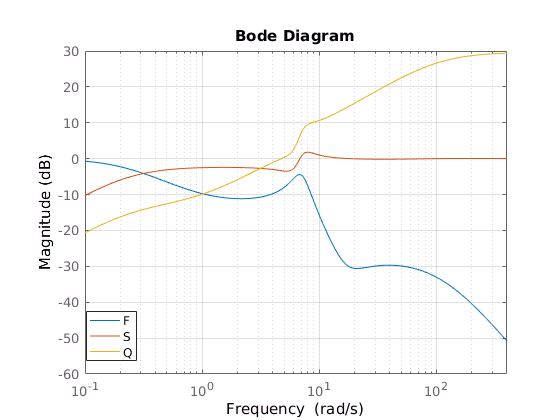

Gq = tf(PitchRateModel);
Fin = (Gq * Mixer * R1) / (1 + Gq * Mixer * R1);
L = integrator * Fin * R2;

F =  L / (1 + L);
S =  1 / (1 + L);
Q = R2 / (1 + L);

figure()
    bode(F, S, Q, bode_no_phase)
    xlim([10^-1, 20^2]);
    legend('F', 'S', 'Q', 'location', 'southWest');

Assuming that figure 7.7 (p91) is showing the Complementary, Sensiistivity and controlo sensitivity functions then I am waaaaay off base. That diagram shows stuff that has a single pole or zero in s = 1. Clearly my results do not match.

Another figure we can use is figure 7.13 (p96). This figure shows the output of the plant given an inut signal that doesn't look too hard to rebuild.

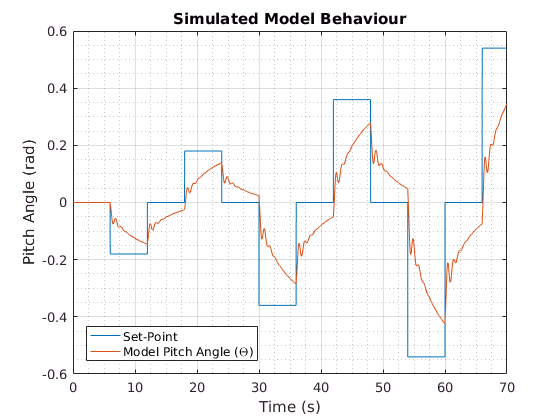

step_size = .18;     % Rough guess from the figures
step_duration = 600; % Estimated 6s per state, 100 samples per second
time_vec = 0:.01:70;

base = ones(1, step_duration);
test_input = [
    base * 0, base * -1 * step_size, base * 0, base * step_size, base * 0, ...
    base * -2 * step_size, base *  0, base * 2 * step_size, base * 0,      ...
    base * -3 * step_size, base *  0, base * 3 * step_size, base * 0,      ...
];

% Crop the input sequence to the size of the time vector
test_input = test_input(1:length(time_vec));
test_pitch_angle = lsim(OuterReferenceModel, test_input, time_vec);

figure();
        plot(time_vec, test_input, time_vec, test_pitch_angle);
        title('Simulated Model Behaviour');
        legend('Set-Point', 'Model Pitch Angle (\Theta)', ...
            'location', 'southWest');
        ylabel('Pitch Angle (rad)'); xlabel('Time (s)');
        grid minor;     

This is starting to look better. The controller is still too slow but at least its trying !

We also have graphs for $q
$ (the inner control variable) and $\delta M$we can try to build as well.

The set-point for the angular rate is simply the output of the outer controller (R2). 

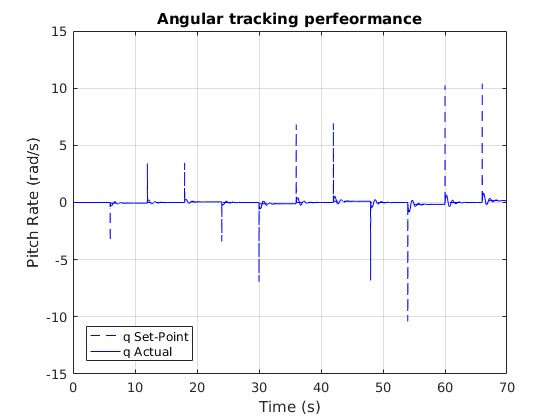

test_input_q = lsim(R2, test_input, time_vec); % This line is wrong !
test_output_q = lsim(InnerReferenceModel, test_input_q, time_vec);

figure()
    plot(time_vec, test_input_q, 'b--', time_vec, test_output_q, 'b');
    legend('q Set-Point', 'q Actual', 'location', 'southWest');
    title('Angular tracking perfeormance');
    xlabel('Time (s)'), ylabel('Pitch Rate (rad/s)');

The angular rate is looking good but it is still completely outside of the range from the paper. Their data has angular rates between  1 and -1, ours is between 15 and -15. Something is still fucked up. 

Next step is to generate the quad-copter input variable $\delta M$. 

% Build $\delta M$